# Dimensional Analysis of Planetesimal Core Formation

Prepare Matlab workspace.

clear all; close all; clc;

## 1. Introduction

Analysis of Hafnium-Tungsten (Hf-W) isotopes suggests early core formation in solar system planetesimals (~10–100 km radius) has taken place on timescales of only few million years (Myr) after their formation. This time scale coincides with a time of intense internal heating due to the decay of $^{26}$Al, a radiogenic isotope with a half-life of ~0.7 Myr.

In this lab, we use dimensional analysis to estimate the time scales required for three physical processes that may have contributed to early core formation (see Fig. below):

- metal diapirs sinking through solid rock

- metal melt percolating through partially molten rock

- metal melt droplets raining out of magma

From fluid mechanics theory we know that these processes obey certain flow laws to a reasonably good approximation. 

In this Lab, you will be guided through the following steps of dimensional analysis of this problem:

- identify transport processes, driving forces, and material resistance

- identify magnitudes and dimensions of all quantities involved

- identify characteristic rates of transport processes 

- identify dimensionless numbers by taking ratios of rates, time, or length scales

- identify regimes within reasonable range of dimensionless numbers

This Matlab Live Script provides both the instructions for your work as well as prepared calculations for you to complete and interpret.

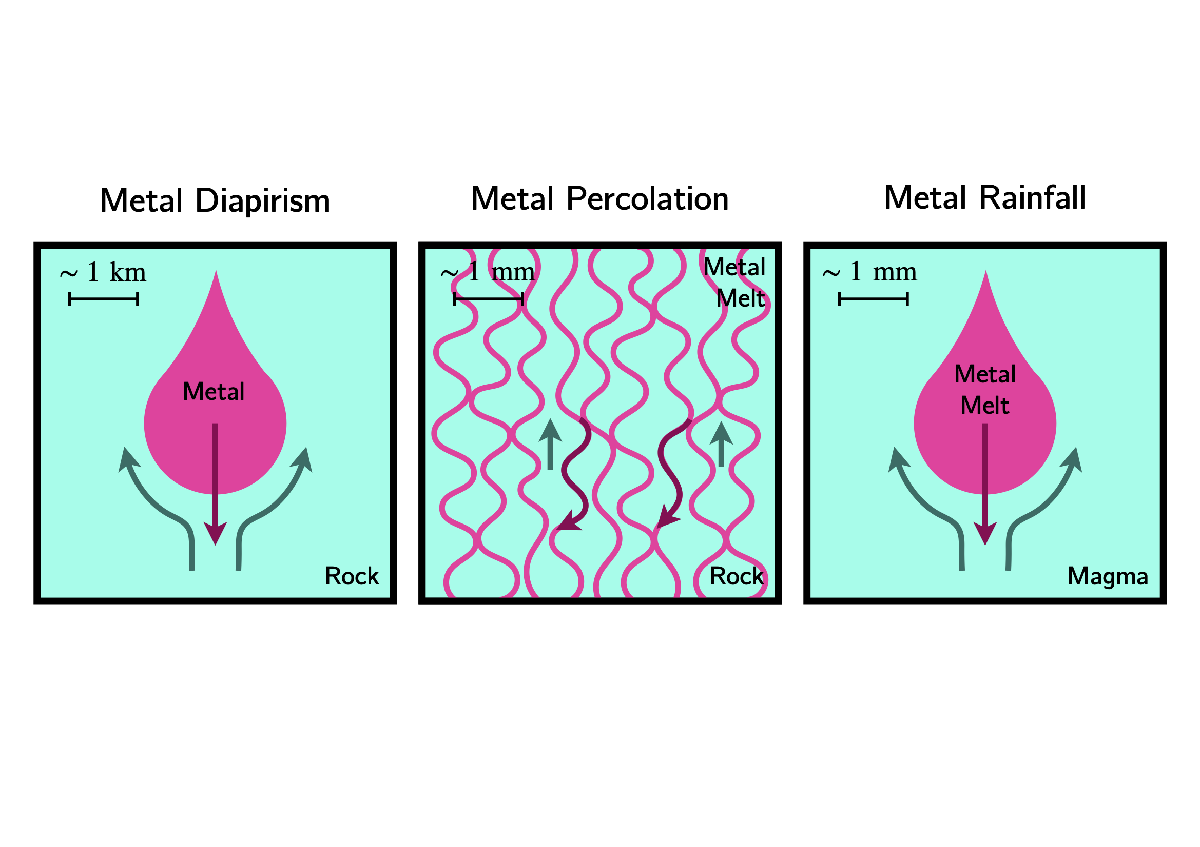

### 1.1 Metal Diapirism

A metal diapir refers to a rounded to tear-drop shaped metal mass sinking through hot, solid rock giving way by viscous creep. The sinking of a diapir approximately follows Stoke's law of a sinking sphere,

(1)        $u_\mathrm{mdp} = {\Delta \rho g R_\mathrm{dpr}^2 \over \eta_\mathrm{rck}}$ ,

where $u_\mathrm{mdp}$ [m/s] is the Stokes sinking speed, $\Delta \rho$ [kg/m$^3$] is the density difference of the diapir to the surrounding medium which drives the sinking motion, $g$ [m/s$^2$] the gravitational acceleration of the planetesimal, $R$ [m] the radius of the diapir, and $\eta_\mathrm{rck}$ [Pa s] the viscosity of the surrounding medium which resists the sinking motion. This law arises from balancing the gravitational driving force of the diapir sinking due to its density contrast, $\sim\Delta \rho g R_\mathrm{dpr}^3$, with the viscous resistance force of the rock surrounding it, $\sim u_\mathrm{mdp} \eta_\mathrm{rck} R_\mathrm{dpr}$. 

Note that some geometric factors of order ~1 have been neglected to produce a simplified order-of-magnitude estimate; [read more under this link.](https://en.wikipedia.org/wiki/Stokes%27_law)

### 1.2 Metal Percolation

Metal percolation refers to a scenario where molten metal is present as melt pockets or films on the grain boundaries of a permeable solid matrix. Melt percolation by porous flow approximately follows Darcy's law of porous flow,

(2)        $u_\mathrm{mpc} = {\Delta \rho g K_\mathrm{rck} \over \eta_\mathrm{mtl}}$ ,

where $u_\mathrm{mpc}$ [m/s] is the Darcy percolation speed, $\Delta \rho$ and $g$ provide the gravitational driving force for melt percolation, and $K_\mathrm{rck}$ is the permeability of the granular rock permitting, and $\eta_\mathrm{mtl}$ the viscosity of the metal melt resisting the percolation. Read more on Darcy's law [under this link](https://en.wikipedia.org/wiki/Darcy%27s_law). 

The rock permeability follows a powerlaw of the form,

(3)        $K_\mathrm{rck} = {r_\mathrm{grn}^2 \phi_\mathrm{mtl}^3 \over b}$ ,

with $r_\mathrm{grn}$ [m] the average grain size in the rock matrix, $b$ a dimensionless factor of order ~100 representing the geometry of melt films on grain boundaries, $\phi_\mathrm{mtl}\sim0.1$ the volume fraction [vol] of metal melt exceeding the percolation threshold. The percolation threshold is the minimum volume fraction at which metal melt transitions from isolated and immobile melt pockets on grain corners to an interconnected drainage network of films and channels along grain boundaries. For example, if all of the 30 vol% of Fe-Ni metal of the example planetesimal is molten, and the percolation threshold for metal melt is 10 vol%, then $\phi_\mathrm{mtl}=0.2$.

### 1.3 Metal Rainfall

The metal rainfall mechanism refers to a scenario where internal heating has melted most of a planetesimal and produced a magma layer or ocean, within which droplets of immiscible metal melt sink through the silicate magma. Metal droplet settling again follows Stokes law as in eq. (1) but  on a different scale,

(4)        $u_\mathrm{mrf} = {\Delta \rho g R_\mathrm{drp}^2 \over \eta_\mathrm{mgm}}$ ,

with $u_\mathrm{mrf}$ the droplet settling speed, and $\Delta \rho$ and $g$ as above; $R_\mathrm{drp}$ refers to the radius of metal droplets (much smaller than the diapir radius above), and $\eta_\mathrm{mgm}$ the viscosity of the silicate magma (much lower than the rock viscosity above).

## 2. Assembly of Scales

We begin our analysis by assembling characteristic scales (i.e., order of magnitude estimates) for the quantities required to estimate the metal sinking speeds for the three processes above. The metal-silicate density difference can be determined by looking up textbook values of Fe-Ni metal, and olivine-pyroxene-feldspar bearing rock. 

***Task 1: ***Find appropriate parameter values to complete the code cell below. Add the correct units in the comments on each line (`xxxx` marks the spot!).

rho_rck = xxxx;             % [xxxx] density of ol-px-fsp rock
rho_mtl = xxxx;             % [xxxx] density of Fe-Ni metal
Drho    = rho_mtl-rho_rck;  % [xxxx] metal-rock density difference
display(Drho)

The gravity of a planetesimal,

(5)        $g = {G M_\mathrm{plt} \over R_\mathrm{plt}^2} $ ,

depends on its mass, $M_\mathrm{plt}=\bar{\rho}V_\mathrm{plt}$, a function of its volume, $V_\mathrm{plt}$, and bulk density, $\bar{\rho}$, and the universal constant of gravitation, $G$.  

***Task 2:*** Calculate the gravity of the planetesimal in the code cell below. Assume the planetesimal is spherical with a radius of 100 km. To calculate the bulk density, assume that the planetesimal is made up of 30 vol% metal to 70% silicate. Find the value and units of the gravitational constant online.

G       = xxxx;             % [xxxx] gravitational constant
R_plt   = xxxx;             % [xxxx] radius of planetesimal
V_plt   = xxxx;             % [xxxx] volume of planetesimal
rho_blk = xxxx;             % [xxxx] bulk density of planetesimal
M_plt   = V_plt*rho_blk;    % [kg] mass of planetesimal
g       = G*M_plt/R_plt^2;  % [m/s2] gravity of planetesimal
display(g)

With characteristic scales for the components of the driving force determined, we now need to identify reasonable estimates for the resisting material parameters, the viscosity of hot, creeping rock for metal diapirism, $\eta_\mathrm{rck}$, the viscosity of the metal melt for metal percolation, $\eta_\mathrm{mtl}$ and the viscosity of silicate magma for metal rainfall, $\eta_\mathrm{mgm}$. 

***Task 3:*** Complete the code cell below with reasonable order-of-magnitude estimates for each of the viscosities. Add the correct units to the comments on each line. Note, the viscosity of solid rock and liquid magma can span quite a range depending on temperature and composition. Choose a representative value for now. You will be able to test a wider range further below.

eta_rck = xxxx;  % [xxxx] characteristic viscosity of hot rock
eta_mtl = xxxx;  % [xxxx] characteristic viscosity of liquid Fe-Ni metal
eta_mgm = xxxx;  % [xxxx] characteristic viscosity of liquid silicates

Finally, we need to identify reasonable estimates for the dimensions of metal diapirs, mineral grain size, and metal droplet size for the three mechanisms. For now, assume that diapirs are ~100 times smaller than the planetesimal, and that mineral grains and metal droplets are of order millimetre. 

***Task 4:*** Enter the appropriate values and units in the code cell below and complete the calculation of the characteristic rock permeability by using the formula in eq. (3) along with the values for $b$, and $\phi_\mathrm{mtl}$ given above.

R_dpr   = xxxx;                     % [xxxx] characteristic diapir radius
r_rck   = xxxx;                     % [xxxx] characteristic grain size
R_drp   = xxxx;                     % [xxxx] characteristic droplet size

b       = xxxx;                     % [xxxx] geometric factor
phi_mtl = xxxx;                     % [xxxx] characteristic metal volume fraction above percolation threshold
K_rck   = r_rck^2/b * (phi_mtl)^3;  % [m2] characteristic rock permeability
display(K_rck)

## 3. Analysis of Scales

### 3.1 Characteristic Rates

We have now assembled characteristic scales for all quantities needed to calculate the characteristic speeds of metal-silicate differentiation by the three processes under consideration. 

***Task 5:*** In the code cell below, use the formulas in eqs (1), (2), and (4) together with the characteristic scales assembled already to calculate the characteristic rates of metal transport for each process. The first one is already provided as example of how it is done. The few lines of code following towards the end of the cell will produce a plot of your results. *How do the rates compare?*

u_mdp = Drho*g*R_dpr^2 / eta_rck;  % [m/s] characteristic speed of metal diapirism
u_mpc = xxxx;  % [xxxx] characteristic speed of metal percolation
u_mrf = xxxx;  % [xxxx] characteristic speed of metal rainfall


% plot characteristic rates
yr = 3600*24*365;  % [s/yr] unit conversion factor from seconds to years
figure(1); set(gcf,'Visible','on');
semilogy(1,u_mdp*yr,'ro',2,u_mpc*yr,'g^',3,u_mrf*yr,'bs','MarkerSize',15,'LineWidth',2); box on;
set(gca,'XTick',[1,2,3],'TickLabelInterpreter','latex','FontSize',16);
xlabel('Process Number','Interpreter','latex','FontSize',20);
ylabel('log$_{10}$ Transport Rate [m/yr]','Interpreter','latex','FontSize',20);
title('Characteristic Rates','Interpreter','latex','FontSize',24);

### 3.1 Characteristic Times

To convert from a rate or speed of a process to its characteristic time we need to specify the characteristic length scale over which it takes place. Here, we are interested in the processes of metal differentiation occuring on the length scale of the planetesimal's radius, $R_\mathrm{plt}$. 

***Task 6:*** In the cell below, use the speed scales in [m/s] and the length scale in [m] arranged such that they combine into units of [s] and hence give the corresponding time scale. Your results will be plotted into a new figure. *How do the calculated time scales compare to isotopic constraints on early planetesimal core formation?*

t_mdp = xxxx;  % [xxxx] characteristic time of metal diapirism
t_mpc = xxxx;  % [xxxx] characteristic time of metal percolation
t_mrf = xxxx;  % [xxxx] characteristic time of metal rainfall


% plot characteristic times
figure(2); set(gcf,'Visible','on');
semilogy(1,t_mdp/yr,'ro',2,t_mpc/yr,'g^',3,t_mrf/yr,'bs','MarkerSize',15,'LineWidth',2); box on;
set(gca,'XTick',[1,2,3],'TickLabelInterpreter','latex','FontSize',16);
xlabel('Process Number','Interpreter','latex','FontSize',20);
ylabel('log$_{10}$ Time Scale [yr]','Interpreter','latex','FontSize',20);
title('Characteristic Times','Interpreter','latex','FontSize',24);

## 4. Interpretation of Regimes

### 4.1 Dimensionless Numbers

To compare two characteristic scales of a problem with same dimensions it is often useful to take their ratio and obtain a dimensionless number that characterises the system's behaviour. Silicate-iron differentiation in early planetesimals is thought to be activated as bodies heat up internally due to the decay of $^{26}$Al, a radioactive isotope of aluminium with a known half-life of $t_{1/2}$ = 717 kyr. If we're interested in whether the processes analysed here are viable on the time-scale of $^{26}$Al-heating in the early solar system, we can take the ratios,

(6)         $\mathrm{D_{mdp}} = {t_{1/2} \over t_\mathrm{mdp}}$ ,    $\mathrm{D_{mpc}} = {t_{1/2} \over t_\mathrm{mdp}}$ ,     $\mathrm{D_{mrf}} = {t_{1/2} \over t_\mathrm{mdp}}$ .

We will call these dimensionless numbers the *differentiation numbers*; they express the characteristic time it would take to differentiate a planetesimal by each of the three processes relative to the decay time of the primary heat source. If any of these differentiation numbers are $\ll 1$, the process is expected to be much slower than the heating time scale, meaning substantial early differentiation is unlikely to be established by that process; conversely, if any are $\gg1$, that differentiation process is expected to make substantial progress as the planetesimal is heating up internally from $^{26}$Al.

***Task 7:*** Complete the code cell below by using eq. (6) to calculate the dimensionless differentiation numbers for the three processes. Your results will be plotted into a new figure. *From the results, which differentiation process would you interpret to be viable on the time scale of  internal heating by decay of *$^{26}$*Al?*

t_1_2 = 7.7e5*yr;      % [s] half-life of 26Al converted to base units
D_mdp = xxxx;   % [xxxx] differentiation number for metal diapirism
D_mpc = xxxx;   % [xxxx] differentiation number for metal percolation
D_mrf = xxxx;   % [xxxx] differentiation number for metal rainfall


% plot dimensionless numbers
figure(3); set(gcf,'Visible','on');
semilogy(1,D_mdp,'ro',2,D_mpc,'g^',3,D_mrf,'bs','MarkerSize',15,'LineWidth',2); box on; hold on;
line([1,3],[1,1],'Color','k','LineStyle',':','LineWidth',2)
set(gca,'XTick',[1,2,3],'TickLabelInterpreter','latex','FontSize',16);
xlabel('Process Number','Interpreter','latex','FontSize',20);
ylabel('log$_{10}$ Dimensionless Number [1]','Interpreter','latex','FontSize',20);
title('Differentiation Numbers','Interpreter','latex','FontSize',24);

### 4.2 Regime Diagrams

By recalling from above the original scales that went into determining the characteristic times of the three differentiation processes, we can now express the differentiation numbers directly as functions of their driving force and material resistance parameters,

(7)        $\mathrm{D_{mdp}} = {t_{1/2}  \over t_\mathrm{mdp}} = {u_\mathrm{mdp} \, t_{1/2} \over R_\mathrm{plt}} = {{\Delta \rho g R_\mathrm{dpr}^2  \, t_{1/2} \over \eta_\mathrm{rck} R_\mathrm{plt}}$ ,

(8)        $\mathrm{D_{mpc}} = {t_{1/2}  \over t_\mathrm{mpc}} = {u_\mathrm{mpc} \, t_{1/2} \over R_\mathrm{plt}} = {{\Delta \rho g r_\mathrm{grn}^2 \phi_\mathrm{mtl}^3 \, t_{1/2} \over b \eta_\mathrm{mtl} R_\mathrm{plt}}$ ,

(9)        $\mathrm{D_{mrf}} = {t_{1/2}  \over t_\mathrm{mrf}} = {u_\mathrm{mrf} \, t_{1/2} \over R_\mathrm{plt}} = {{\Delta \rho g R_\mathrm{drp}^2  \, t_{1/2} \over \eta_\mathrm{mgm} R_\mathrm{plt}}$ .

With the density difference, the radius and therefore gravity of the planetesimal, the viscosity of metal melt, and the half-life of the heat source isotope remaining the same, we can now interpret reasonable regimes of planetary differentiation by investigating how differentiation numbers change over an appropriate range of the more uncertain parameters:

- diapir radius and rock viscosity in metal diapirism

- rock grain size and metal volume fraction in metal percolation

- droplet radius and magma viscosity in metal rainfall

For this last part of the analysis, we will set lower and upper estimates for each of the parameters and generate a 2-D grid with one parameter range each on the x-axis and y-axis. We will then calculate the relevant differentiation number over this combined parameter space and visualise it as a 2-D contour map.

***Task 8:*** In the three prepared code cells below, enter reasonable lower and upper estimates for each parameter. These will be used to produce regime diagrams showing how the differentiation number of each process varies across the given parameter space. *From the regime diagrams, determine the section of the parameter space in which each of the processes may be viable on the time scales required by coscmochemical constraints.*

#### 4.2.1 Metal Diapirism

% metal diapirism regime diagram
R_dpr_lower   = xxxx;  % [xxxx] lower estimate diapir radius
R_dpr_upper   = xxxx;  % [xxxx] upper estimate diapir radius

eta_rck_lower = xxxx;  % [xxxx] lower estimate viscosity of hot rock
eta_rck_upper = xxxx;  % [xxxx] upper estimate viscosity of hot rock


% generate grid of parameter space
R = 10.^linspace(log10(R_dpr_lower  ),log10(R_dpr_upper  ),100);
E = 10.^linspace(log10(eta_rck_lower),log10(eta_rck_upper),100);
[RR,EE] = meshgrid(R,E);

% calculate differentiation number over parameter space
D_mdp = Drho.*g.*RR.^2.*t_1_2 ./ (EE.*R_plt);

% plot regime diagram as contour map
figure(4); clf; set(gcf,'Visible','on');
contourf(log10(RR),log10(EE),log10(D_mdp),10,'LineWidth',2); axis tight; box on; colorbar('FontSize',16,'TickLabelInterpreter','latex'); hold on;
contour (log10(RR),log10(EE),log10(D_mdp),[0,0],'LineWidth',3,'LineColor','k','LineStyle','--');
legend('$D_\mathrm{mdp}$','$D_\mathrm{mdp} = 1$','Interpreter','latex','box','on','FontSize',20);
set(gca,'TickLabelInterpreter','latex','FontSize',16);
xlabel('log$_{10}$ Diapir Radius [m]','Interpreter','latex','FontSize',20);
ylabel('log$_{10}$ Rock Viscosity [Pas]','Interpreter','latex','FontSize',20);
title('Regime Diagram -- Metal Diapirism','Interpreter','latex','FontSize',24);

#### 4.2.2 Metal Percolation

% metal percolation regime diagram
r_rck_lower   = xxxx;  % [xxxx] lower estimate grain size
r_rck_upper   = xxxx;  % [xxxx] upper estimate grain size

phi_mtl_lower = xxxx;  % [xxxx] lower estimate metal volume fraction above percolation threshold
phi_mtl_upper = xxxx;  % [xxxx] upper estimate metal volume fraction above percolation threshold


% generate grid of parameter space
R = 10.^linspace(log10(r_rck_lower  ),log10(r_rck_upper  ),100);
F = 10.^linspace(log10(phi_mtl_lower),log10(phi_mtl_upper),100);
[RR,FF] = meshgrid(R,F);

% calculate differentiation number over parameter space
D_mpc = Drho.*g.*RR.^2.*FF.^3.*t_1_2 ./ (b.*eta_mtl.*R_plt);

% plot regime diagram as contour map
figure(5); clf; set(gcf,'Visible','on');
contourf(log10(RR),log10(FF),log10(D_mpc),10,'LineWidth',2); axis tight; box on; colorbar('FontSize',16,'TickLabelInterpreter','latex'); hold on;
contour (log10(RR),log10(FF),log10(D_mpc),[0,0],'LineWidth',3,'LineColor','k','LineStyle','--');
legend('$D_\mathrm{mpc}$','$D_\mathrm{mpc} = 1$','Interpreter','latex','box','on','FontSize',20);
set(gca,'TickLabelInterpreter','latex','FontSize',16);
xlabel('log$_{10}$ Grain Size [m]','Interpreter','latex','FontSize',20);
ylabel('log$_{10}$ Metal Melt Fraction [vol]','Interpreter','latex','FontSize',20);
title('Regime Diagram -- Metal Percolation','Interpreter','latex','FontSize',24);

#### 4.2.3 Metal Rainfall

% metal diapirism regime diagram
R_drp_lower   = xxxx;  % [xxxx] lower estimate droplet radius
R_drp_upper   = xxxx;  % [xxxx] upper estimate droplet radius

eta_mgm_lower = xxxx;  % [xxxx] lower estimate viscosity of magma
eta_mgm_upper = xxxx;  % [xxxx] upper estimate viscosity of magma


% generate grid of parameter space
R = 10.^linspace(log10(R_drp_lower  ),log10(R_drp_upper  ),100);
E = 10.^linspace(log10(eta_mgm_lower),log10(eta_mgm_upper),100);
[RR,EE] = meshgrid(R,E);

% calculate differentiation number over parameter space
D_mrf = Drho.*g.*RR.^2.*t_1_2 ./ (EE.*R_plt);

% plot regime diagram as contour map
figure(6); clf; set(gcf,'Visible','on');
contourf(log10(RR),log10(EE),log10(D_mrf),10,'LineWidth',2); axis tight; box on; colorbar('FontSize',16,'TickLabelInterpreter','latex'); hold on;
contour (log10(RR),log10(EE),log10(D_mrf),[0,0],'LineWidth',3,'LineColor','k','LineStyle','--');
legend('$D_\mathrm{mdp}$','$D_\mathrm{mdp} = 1$','Interpreter','latex','box','on','FontSize',20);
set(gca,'TickLabelInterpreter','latex','FontSize',16);
xlabel('log$_{10}$ Droplet Radius [m]','Interpreter','latex','FontSize',20);
ylabel('log$_{10}$ Magma Viscosity [Pas]','Interpreter','latex','FontSize',20);
title('Regime Diagram -- Metal Rainfall','Interpreter','latex','FontSize',24);